readtable("D:\EVA\Khushin\Excel file.xlsx")

ans = 10×17 table
     Alpha     AnalysisMethod    Beta       CDi           CDo          CDt          CDtot       CDtott         CFx            CFy           CFz          CL            CMx           CMy           CMz            CS            E   
    _______    ______________    ____    __________    _________    __________    _________    _________    __________    ___________    _________    _________    ___________    _________    ___________    

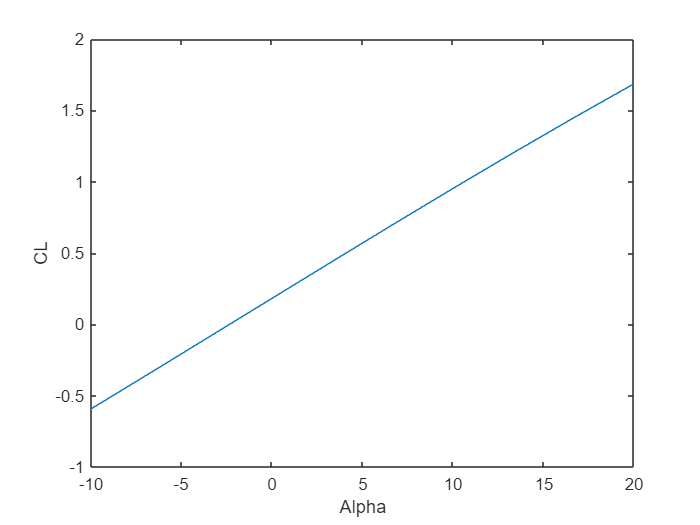

Alpha = Excelfile.Alpha;
beta = Excelfile.Beta;
CL = Excelfile.CL;
CD = Excelfile.CDtott;
Cy = Excelfile.CS;
CMx = Excelfile.CMx;
CMy = Excelfile.CMy;
CMz = Excelfile.CMz;
plot(Alpha, CL)
xlabel('Alpha')
ylabel('CL')

p = polyfit(Alpha, CL, 1);
m = p(1, 1)

m = 0.0763

c = p(1, 2)

c = 0.1791

if m>0 
    fprintf('Lift curve slope is positive resulting in increase in lift generation as angle of attack is increased');
elseif m == 0
    fprintf('Lift curve slope is zero, same amount of lift is generated at any angle of attack');
else
    fprintf('Lift curve slope is negative therefore the aircraft is statically unstable.');
end

Lift curve slope is positive resulting in increase in lift generation as angle of attack is increased

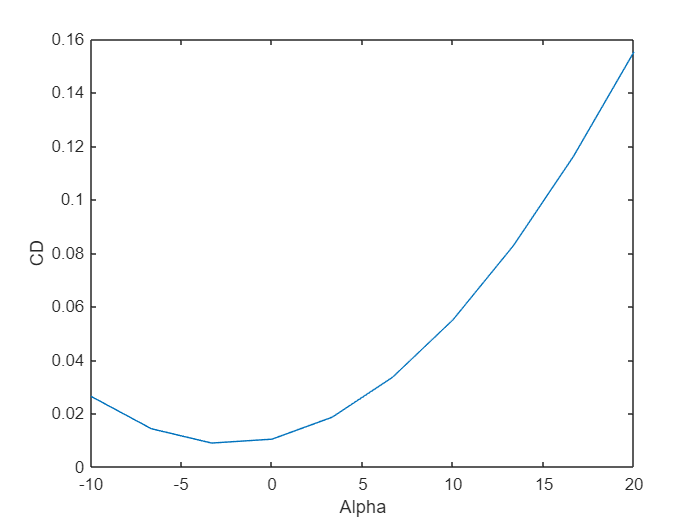

plot(Alpha, CD)
xlabel('Alpha')
ylabel('CD')

p2 = polyfit(Alpha, CD, 1);
m2 = p2(1, 1)

m2 = 0.0043

c2 = p2(1, 2)

c2 = 0.0304

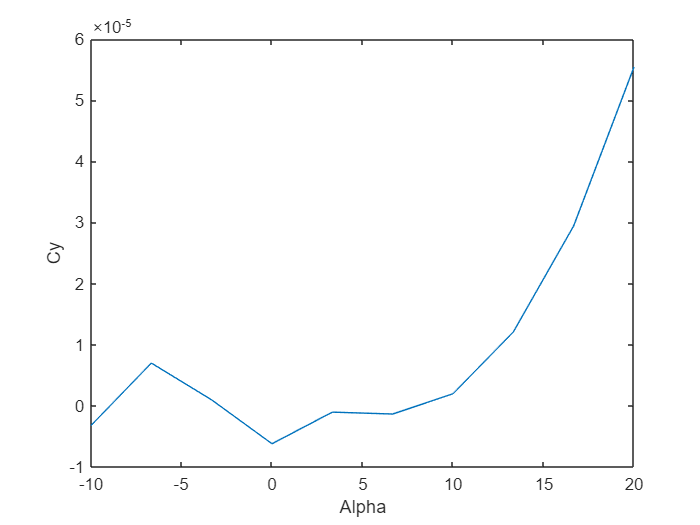


plot(Alpha, Cy)
xlabel('Alpha')
ylabel('Cy')

p3 = polyfit(Alpha, Cy, 1);
m3 = p3(1, 1)

m3 = 1.3901e-06

c3 = p3(1, 2)

c3 = 2.5626e-06

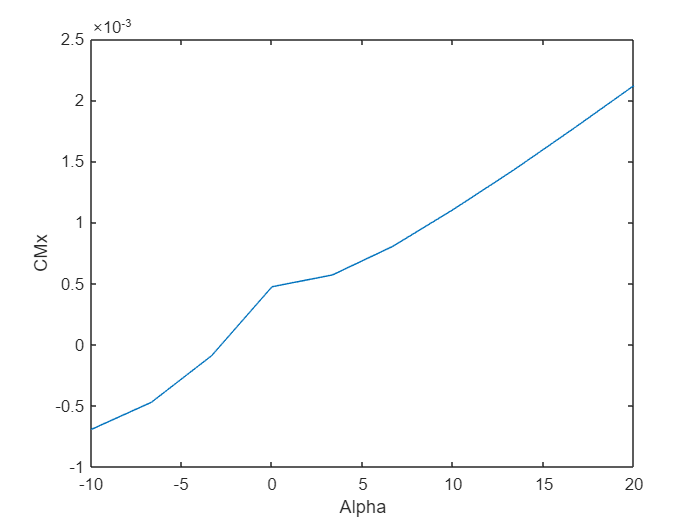


plot(Alpha, CMx)
xlabel('Alpha')
ylabel('CMx')

p3 = polyfit(Alpha, CMx, 1);
m3 = p3(1, 1)

m3 = 9.2190e-05

c3 = p3(1, 2)

c3 = 2.4042e-04

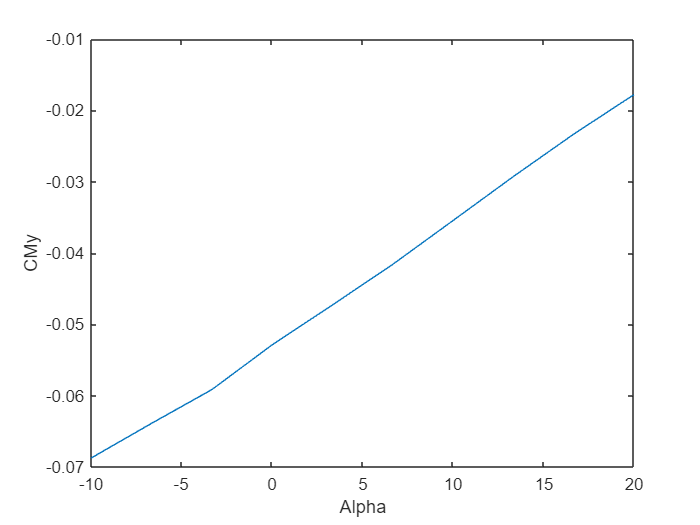


plot(Alpha, CMy)
xlabel('Alpha')
ylabel('CMy')

p4 = polyfit(Alpha, CMy, 1);
m4 = p4(1, 1)

m4 = 0.0017

c4 = p4(1, 2)

c4 = -0.0526

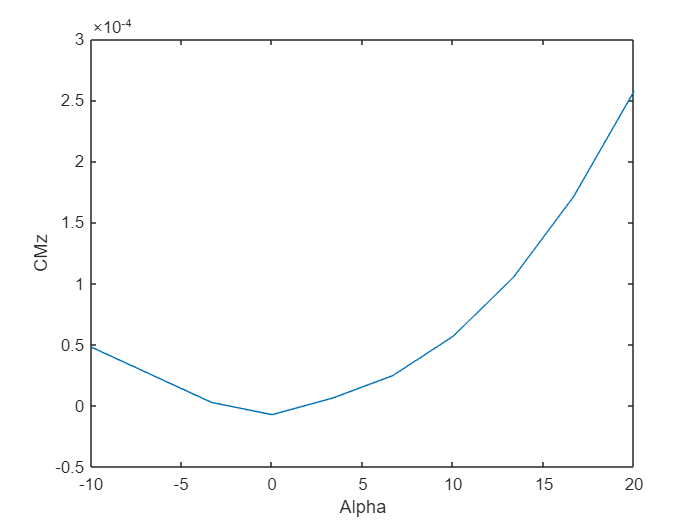


plot(Alpha, CMz)
xlabel('Alpha')
ylabel('CMz')

p5 = polyfit(Alpha, CMz, 1);
m5 = p5(1, 1)

m5 = 6.5875e-06

c5 = p5(1, 2)

c5 = 3.6110e-05